## (Self note) mpc_2.mlx differs from mpc.mlx by allowing floating x and y in our trajectories. We're still using rounded x and y with lookup table instead of using interpolation

clear all;
clc;
clf;

## Elevation, Soil, and Visibility data

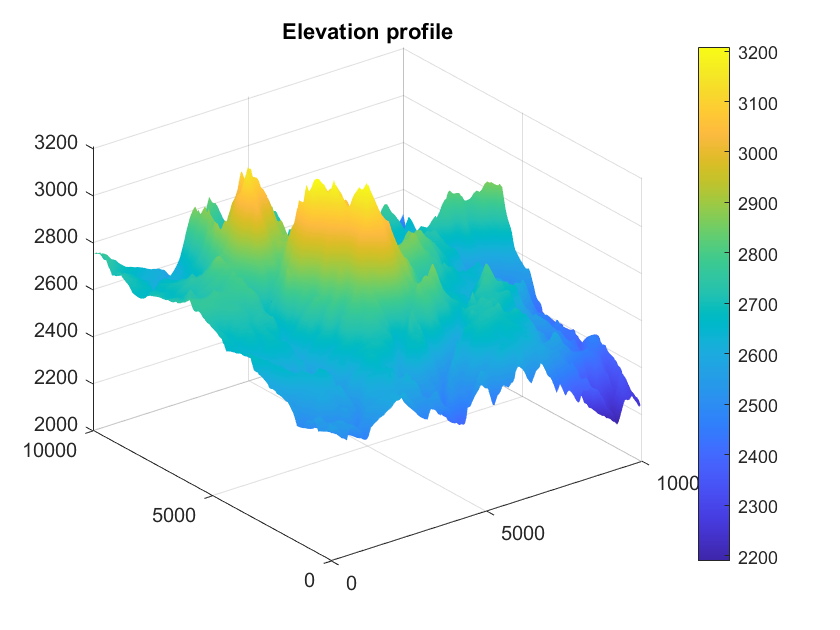

global x_min x_max y_min y_max;

ZM = load('map.txt');
soil = load('soil.txt');
vis = load('visibility.txt');

xv = [0:50:50*(size(ZM,2)-1)];
XM = zeros(size(ZM,2));
for i=1:size(ZM,2)
    XM(i,:) = xv;
end

yv = [0:50:50*(size(ZM,1)-1)]';
YM = zeros(size(ZM,1));
for i=1:size(ZM,1)
    YM(:,i) = yv;
end

clear xv yv;

% Finding min/max for x & y
x_min = min(min(XM));       % This was very computationally expensive if done within the cost function
x_max = max(max(XM));
y_min = min(min(YM));
y_max = max(max(YM));

figure(1);
surf(XM, YM, ZM);
title("Elevation profile");
shading interp;
lims = caxis;
colorbar;

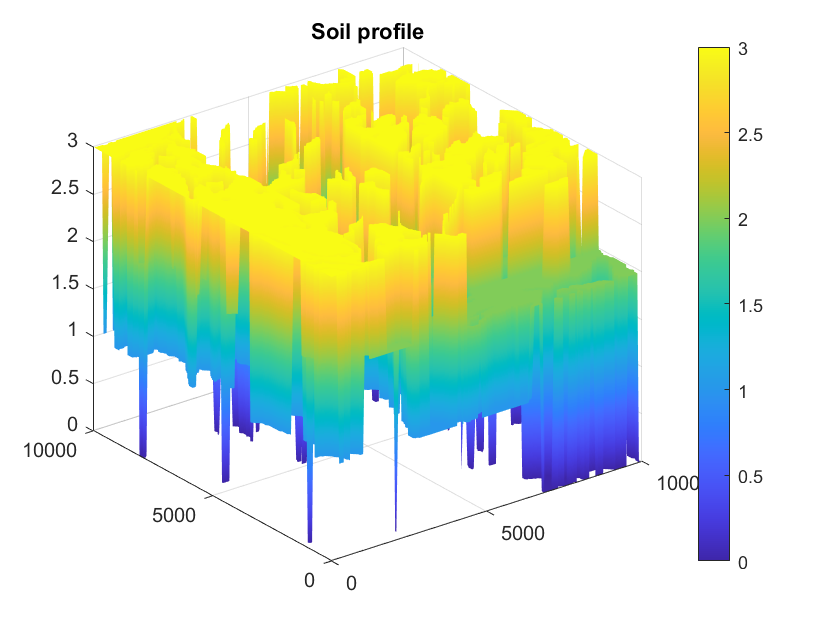

figure(2);
surf(XM,YM,soil);
title("Soil profile");
shading interp;
cmap = colormap;
colorbar;

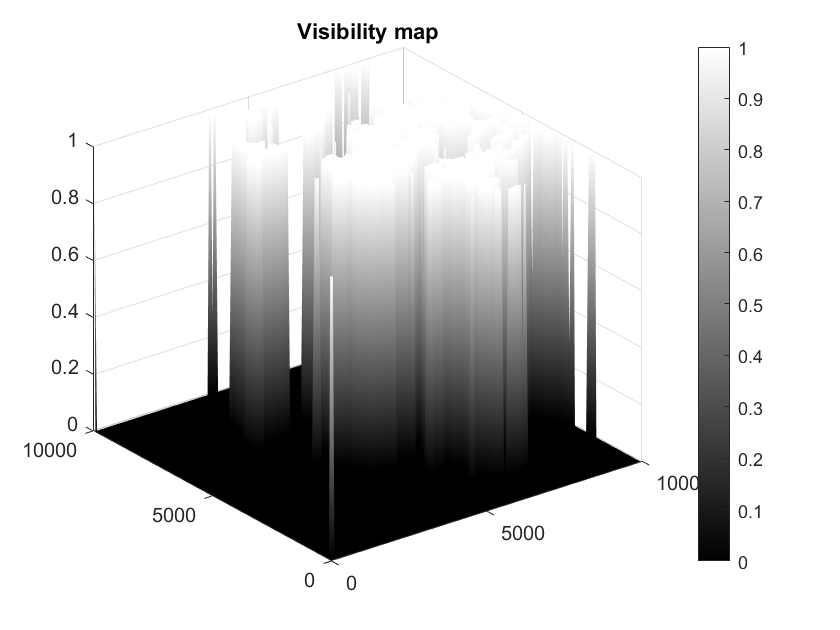

figure(3);
surf(XM,YM,vis);
title("Visibility map");
shading interp;
colormap gray;
colorbar;

## High Resolution Data (Interpolated)

%% X and Y matrices with 1 meter intervals
global Xm Ym;

xv = [0:1:9950];
Xm = zeros(length(xv)); % high resolution x
for i=1:length(xv)
    Xm(i,:) = xv;
end

yv = [0:1:9950]';
Ym = zeros(length(yv)); % high resolution y
for i=1:length(yv)
    Ym(:,i) = yv;
end

clear xv yv;

% High-res Elevation data
global Zm;
Zm = interp2(XM, YM, ZM, Xm, Ym); % high resolution z

% High-res soil data
global soilm;
soilm = interp2(XM, YM, soil, Xm, Ym); % high resolution soil map

% High-res visibility data
global vism;
vism = interp2(XM, YM, vis, Xm, Ym); % high resolution visibility map

% figure(4);
% surf(Zm(1:2500, 1:2500));
% %caxis(lims);
% shading interp;
% colorbar;

## Dynamic Programming

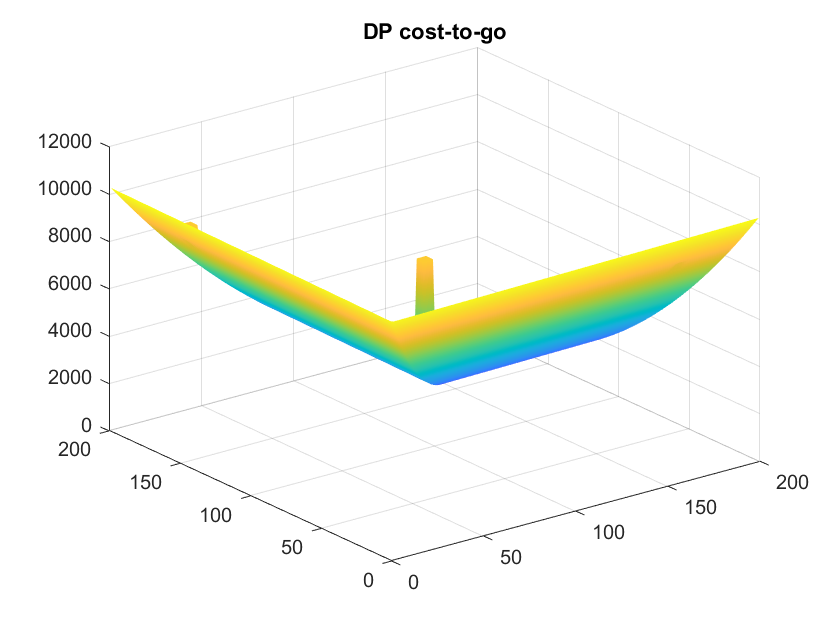

% Implement DP here
% Assuming obtained cost-to-go map as follows:
costDP = zeros(size(ZM));
lastMin = -1;
for i=200:-1:1
    vecLen = 200 - (i-1);
    maxPt = lastMin + vecLen;
    minPt = lastMin + 1;
    vec = [minPt:maxPt];
    costDP(i:200,i) = vec';
    costDP(i,i:200) = vec;
    lastMin = mean([minPt, maxPt]);
end

% Adding random peaks
costDP(170:175, 20:25) = 9000;
costDP(20:25, 170:175) = 9000;
costDP(75:80,75:80) = 9000;

surf(costDP);
title("DP cost-to-go");
colormap(cmap);
shading interp;

clear lastMin vecLen vec maxPt minPt cmap lims;

## High Resolution DP cost-to-go (Interpolated)

costDPm = interp2(XM, YM, costDP, Xm, Ym);

## MPC Parameters

%%%%%%%%%%%%%% MPC parameters %%%%%%%%%%%%%%
global Np;
global w1 w2 w3 w4 w5;  % Individual cost weights

% Prediction horizon
Np = 25;    

% Cost weights
w1 = 1;
w2 = 1;
w3 = 1;
w4 = 1;
w5 = 1;

% Input constraint limits
delta_max = (pi/3);
delta_dot_max = delta_max/0.15;

% fmincon options
options = optimoptions('fmincon','Display','off');

## Model Predictive Controller

%%%%%%%%%%%%%% Inequality constraint matrix A %%%%%%%%%%%%%%
A = zeros(2*(Np-1)+2*(Np-3), Np);
% Constraints on max delta
for i=1:(Np-1)
    A(i,i) = -1;
    A(i,i+1) = 1;
end
for i=Np:2*(Np-1)
    A(i,i-Np+1) = 1;
    A(i,i-Np+2) = -1;
end
% Constraints on max delta_rate
for i=2*(Np-1)+1:2*(Np-1)+(Np-3)
    A(i,i-2*(Np-1)+3) = 1;
    A(i,i-2*(Np-1)+2) = -1;
    A(i,i-2*(Np-1)+1) = -1;
    A(i,i-2*(Np-1)) = 1;
end
for i=2*(Np-1)+(Np-3)+1:size(A,1)
    A(i,i-(3*Np-5)+3) = -1;
    A(i,i-(3*Np-5)+2) = 1;
    A(i,i-(3*Np-5)+1) = 1;
    A(i,i-(3*Np-5)) = -1;
end

%%%%%%%%%%%%%% Inequality constraint matrix B (delta max/ max steering input) %%%%%%%%%%%%%%
B = ones(2*(Np-1)+2*(Np-3),1);
B(1:Np-1) = delta_max*B(1:Np-1);
B(Np:2*(Np-1)) = -delta_max*B(Np:2*(Np-1));
B(2*(Np-1)+1:2*(Np-1)+(Np-3)) = delta_dot_max*B(2*(Np-1)+1:2*(Np-1)+(Np-3));
B(2*(Np-1)+(Np-3)+1:size(B,1)) = -delta_dot_max*B(2*(Np-1)+(Np-3)+1:size(B,1));

%%%%%%%%%%%%%% Running MPC for the whole journey %%%%%%%%%%%%%%
% Storing control history
u_opt = zeros(10*size(Xm,1),1);   % Declaring extra large vector because we don't know number of control inputs required
num_u = 0;  % will update from loop

% Storing optimal state trajectory
x_traj = zeros(size(u_opt));
y_traj = zeros(size(u_opt));

% Starting at (0,0)
global x_start y_start x_end y_end;
x_start = Xm(1,1);
y_start = Ym(1,1);

while ((x_start ~= Xm(end,end)) && (y_start ~= Ym(end,end))) && (num_u <= 100)% 0.4*size(u_opt,1))
    tic

    % Possible delta_s, x and y
    pos_u = [0: pi/180: 359*pi/180];    % possible heading angles in radians
    pos_xN = x_start + Np*cos(pos_u);   % Np is the radius at Nth step
    pos_yN = y_start + Np*sin(pos_u);

    %% Filter out out-of-bound x & y
    % Finding indices of infeasible x and y
    notpos_xN_ind = (pos_xN < x_min) | (pos_xN > x_max);
    notpos_yN_ind = (pos_yN < y_min) | (pos_yN > y_max);
    % Assigning NaN to x values based on infeasible x & y indices
    pos_xN(notpos_xN_ind) = NaN;
    pos_xN(notpos_yN_ind) = NaN;
    % Assigning NaN to y values based on infeasible x & y indices
    pos_yN(notpos_xN_ind) = NaN;
    pos_yN(notpos_yN_ind) = NaN;
    % Removing NaN pairs from the vectors representing possible x & y pairs 
    pos_xN = pos_xN(~isnan(pos_xN));
    pos_yN = pos_yN(~isnan(pos_yN));
    % Find (xN, yN) pair with minimum cost-to-go
    [minCost, I] = min(costDPm(sub2ind(size(costDPm), round(pos_xN)+1, round(pos_yN)+1))); % Assuming cost-to-go at (32.28, 43.31) should be very close to that at (32,43)
    x_end = pos_xN(I);
    y_end = pos_yN(I);
  
    %% Run fmincon for this kth step
    u_init = atan((y_end - y_start)/(x_end - x_start)); % Calculating initial u for faster fmincon convergence
    u_cal = fmincon(@mpcCostFunction, u_init*ones(Np,1), [], [], [], [], [], [], [], options);
    num_u = num_u + 1;
    u_opt(num_u) = u_cal(1);

    % Update x_start and y_start
    x_start = x_start + 1*cos(u_opt(num_u));    % delta_s for the 1st step is equal to r = 1 meter
    y_start = y_start + 1*sin(u_opt(num_u));

    % Saving trajectory for later visualization
    x_traj(num_u+1) = x_start;
    y_traj(num_u+1) = y_start;

    toc
    fprintf("num_u = %d, ", num_u);
    fprintf("x = %0.2f, ", x_start);
    fprintf("y = %0.2f\n", y_start);
%     if (mod(num_u,100) == 0)
%         fprintf("num_u = %d\n", num_u);
%     end
end

Elapsed time is 0.213867 seconds.


num_u = 1, 

x = 0.71, 

y = 0.71


Elapsed time is 0.053887 seconds.


num_u = 2, 

x = 1.40, 

y = 1.43


Elapsed time is 0.033765 seconds.


num_u = 3, 

x = 2.12, 

y = 2.12


Elapsed time is 0.026919 seconds.


num_u = 4, 

x = 2.83, 

y = 2.83


Elapsed time is 0.089807 seconds.


num_u = 5, 

x = 3.54, 

y = 3.54


Elapsed time is 0.020838 seconds.


num_u = 6, 

x = 4.27, 

y = 4.22


Elapsed time is 0.016487 seconds.


num_u = 7, 

x = 4.99, 

y = 4.91


Elapsed time is 0.015619 seconds.


num_u = 8, 

x = 5.69, 

y = 5.62


Elapsed time is 0.015999 seconds.


num_u = 9, 

x = 6.42, 

y = 6.30


Elapsed time is 0.016162 seconds.


num_u = 10, 

x = 7.14, 

y = 7.00


Elapsed time is 0.015620 seconds.


num_u = 11, 

x = 7.85, 

y = 7.70


Elapsed time is 0.014792 seconds.


num_u = 12, 

x = 8.58, 

y = 8.38


Elapsed time is 0.014721 seconds.


num_u = 13, 

x = 9.30, 

y = 9.08


Elapsed time is 0.015923 seconds.


num_u = 14, 

x = 10.01, 

y = 9.79


Elapsed time is 0.015522 seconds.


num_u = 15, 

x = 10.75, 

y = 10.46


Elapsed time is 0.130461 seconds.


num_u = 16, 

x = 11.48, 

y = 11.14


Elapsed time is 0.057344 seconds.


num_u = 17, 

x = 12.20, 

y = 11.83


Elapsed time is 0.016272 seconds.


num_u = 18, 

x = 12.91, 

y = 12.54


Elapsed time is 0.016220 seconds.


num_u = 19, 

x = 13.64, 

y = 13.22


Elapsed time is 0.016016 seconds.


num_u = 20, 

x = 14.36, 

y = 13.92


Elapsed time is 0.016827 seconds.


num_u = 21, 

x = 15.07, 

y = 14.62


Elapsed time is 0.015693 seconds.


num_u = 22, 

x = 15.80, 

y = 15.30


Elapsed time is 0.016099 seconds.


num_u = 23, 

x = 16.48, 

y = 16.04


Elapsed time is 0.016815 seconds.


num_u = 24, 

x = 17.19, 

y = 16.74


Elapsed time is 0.016311 seconds.


num_u = 25, 

x = 17.88, 

y = 17.46


Elapsed time is 0.015880 seconds.


num_u = 26, 

x = 18.61, 

y = 18.14


Elapsed time is 0.016780 seconds.


num_u = 27, 

x = 19.33, 

y = 18.84


Elapsed time is 0.016937 seconds.


num_u = 28, 

x = 20.04, 

y = 19.55


Elapsed time is 0.015639 seconds.


num_u = 29, 

x = 20.77, 

y = 20.23


Elapsed time is 0.016508 seconds.


num_u = 30, 

x = 21.49, 

y = 20.92


Elapsed time is 0.015347 seconds.


num_u = 31, 

x = 22.20, 

y = 21.63


Elapsed time is 0.016030 seconds.


num_u = 32, 

x = 22.89, 

y = 22.35


Elapsed time is 0.019008 seconds.


num_u = 33, 

x = 23.58, 

y = 23.08


Elapsed time is 0.016252 seconds.


num_u = 34, 

x = 24.28, 

y = 23.79


Elapsed time is 0.016160 seconds.


num_u = 35, 

x = 24.98, 

y = 24.51


Elapsed time is 0.015596 seconds.


num_u = 36, 

x = 25.71, 

y = 25.19


Elapsed time is 0.051295 seconds.


num_u = 37, 

x = 26.43, 

y = 25.88


Elapsed time is 0.065498 seconds.


num_u = 38, 

x = 27.13, 

y = 26.59


Elapsed time is 0.015805 seconds.


num_u = 39, 

x = 27.83, 

y = 27.31


Elapsed time is 0.049197 seconds.


num_u = 40, 

x = 28.55, 

y = 28.00


Elapsed time is 0.058153 seconds.


num_u = 41, 

x = 29.26, 

y = 28.71


Elapsed time is 0.016294 seconds.


num_u = 42, 

x = 29.95, 

y = 29.43


Elapsed time is 0.075071 seconds.


num_u = 43, 

x = 30.67, 

y = 30.13


Elapsed time is 0.023124 seconds.


num_u = 44, 

x = 31.43, 

y = 30.78


Elapsed time is 0.018158 seconds.


num_u = 45, 

x = 32.12, 

y = 31.50


Elapsed time is 0.015638 seconds.


num_u = 46, 

x = 32.85, 

y = 32.18


Elapsed time is 0.015660 seconds.


num_u = 47, 

x = 33.55, 

y = 32.90


Elapsed time is 0.015530 seconds.


num_u = 48, 

x = 34.25, 

y = 33.61


Elapsed time is 0.020515 seconds.


num_u = 49, 

x = 34.95, 

y = 34.33


Elapsed time is 0.060612 seconds.


num_u = 50, 

x = 35.63, 

y = 35.06


Elapsed time is 0.022327 seconds.


num_u = 51, 

x = 36.34, 

y = 35.77


Elapsed time is 0.018227 seconds.


num_u = 52, 

x = 37.03, 

y = 36.49


Elapsed time is 0.015467 seconds.


num_u = 53, 

x = 37.76, 

y = 37.17


Elapsed time is 0.015573 seconds.


num_u = 54, 

x = 38.48, 

y = 37.86


Elapsed time is 0.016502 seconds.


num_u = 55, 

x = 39.19, 

y = 38.57


Elapsed time is 0.016311 seconds.


num_u = 56, 

x = 39.88, 

y = 39.29


Elapsed time is 0.016896 seconds.


num_u = 57, 

x = 40.60, 

y = 39.98


Elapsed time is 0.016882 seconds.


num_u = 58, 

x = 41.31, 

y = 40.69


Elapsed time is 0.019556 seconds.


num_u = 59, 

x = 42.01, 

y = 41.41


Elapsed time is 0.016656 seconds.


num_u = 60, 

x = 42.72, 

y = 42.11


Elapsed time is 0.063010 seconds.


num_u = 61, 

x = 43.48, 

y = 42.76


Elapsed time is 0.018018 seconds.


num_u = 62, 

x = 44.17, 

y = 43.48


Elapsed time is 0.017005 seconds.


num_u = 63, 

x = 44.91, 

y = 44.16


Elapsed time is 0.018614 seconds.


num_u = 64, 

x = 45.63, 

y = 44.86


Elapsed time is 0.058914 seconds.


num_u = 65, 

x = 46.33, 

y = 45.56


Elapsed time is 0.016950 seconds.


num_u = 66, 

x = 47.03, 

y = 46.28


Elapsed time is 0.016002 seconds.


num_u = 67, 

x = 47.75, 

y = 46.98


Elapsed time is 0.053402 seconds.


num_u = 68, 

x = 48.46, 

y = 47.68


Elapsed time is 0.015841 seconds.


num_u = 69, 

x = 49.15, 

y = 48.40


Elapsed time is 0.016319 seconds.


num_u = 70, 

x = 49.87, 

y = 49.10


Elapsed time is 0.015946 seconds.


num_u = 71, 

x = 50.54, 

y = 49.84


Elapsed time is 0.064528 seconds.


num_u = 72, 

x = 51.25, 

y = 50.54


Elapsed time is 0.016969 seconds.


num_u = 73, 

x = 51.95, 

y = 51.26


Elapsed time is 0.017667 seconds.


num_u = 74, 

x = 52.67, 

y = 51.95


Elapsed time is 0.057915 seconds.


num_u = 75, 

x = 53.38, 

y = 52.66


Elapsed time is 0.015939 seconds.


num_u = 76, 

x = 54.07, 

y = 53.38


Elapsed time is 0.015860 seconds.


num_u = 77, 

x = 54.79, 

y = 54.07


Elapsed time is 0.057640 seconds.


num_u = 78, 

x = 55.46, 

y = 54.81


Elapsed time is 0.015376 seconds.


num_u = 79, 

x = 56.16, 

y = 55.53


Elapsed time is 0.021271 seconds.


num_u = 80, 

x = 56.85, 

y = 56.25


Elapsed time is 0.081730 seconds.


num_u = 81, 

x = 57.57, 

y = 56.94


Elapsed time is 0.020342 seconds.


num_u = 82, 

x = 58.28, 

y = 57.65


Elapsed time is 0.015518 seconds.


num_u = 83, 

x = 58.97, 

y = 58.37


Elapsed time is 0.015441 seconds.


num_u = 84, 

x = 59.69, 

y = 59.07


Elapsed time is 0.065302 seconds.


num_u = 85, 

x = 60.41, 

y = 59.77


Elapsed time is 0.016393 seconds.


num_u = 86, 

x = 61.10, 

y = 60.49


Elapsed time is 0.061047 seconds.


num_u = 87, 

x = 61.83, 

y = 61.17


Elapsed time is 0.067165 seconds.


num_u = 88, 

x = 62.55, 

y = 61.86


Elapsed time is 0.056200 seconds.


num_u = 89, 

x = 63.27, 

y = 62.56


Elapsed time is 0.014679 seconds.


num_u = 90, 

x = 63.96, 

y = 63.28


Elapsed time is 0.015411 seconds.


num_u = 91, 

x = 64.68, 

y = 63.98


Elapsed time is 0.057194 seconds.


num_u = 92, 

x = 65.39, 

y = 64.68


Elapsed time is 0.015469 seconds.


num_u = 93, 

x = 66.09, 

y = 65.40


Elapsed time is 0.014392 seconds.


num_u = 94, 

x = 66.81, 

y = 66.09


Elapsed time is 0.057780 seconds.


num_u = 95, 

x = 67.48, 

y = 66.84


Elapsed time is 0.016485 seconds.


num_u = 96, 

x = 68.18, 

y = 67.54


Elapsed time is 0.016190 seconds.


num_u = 97, 

x = 68.88, 

y = 68.26


Elapsed time is 0.016001 seconds.


num_u = 98, 

x = 69.60, 

y = 68.96


Elapsed time is 0.054257 seconds.


num_u = 99, 

x = 70.31, 

y = 69.66


Elapsed time is 0.015247 seconds.


num_u = 100, 

x = 71.00, 

y = 70.38


Elapsed time is 0.014983 seconds.


num_u = 101, 

x = 71.72, 

y = 71.07


clear pos_xN pos_yN notpos_xN_ind notpos_yN_ind xNyN_pairs pos_u;

function J = mpcCostFunction(u)
global x_start y_start x_end y_end;
global x_min y_min x_max y_max;
global Xm Ym;
global Zm soilm vism;
global w1 w2 w3 w4 w5;
global Np;

    % vectors to store resultant x & y trajectories using control seq u
    x = zeros(Np+1,1);
    y = zeros(Np+1,1);

    % Initialize x and y
    x(1) = x_start;
    y(1) = y_start;

    for i=1:Np
        % Calculating the next x & y (at k+1) 
        tau = (x(i) - x_start)*cos(u(i)) + (y(i) - y_start)*sin(u(i));
        delta_s = sqrt((2*(i-1)+1) + (tau^2)) - tau;    % k starts from 0 in this formula
        x(i+1) = x(i) + delta_s*cos(u(i));
        y(i+1) = y(i) + delta_s*sin(u(i));

        % Checking for x(i+1) and y(i+1) to be within bounds
        if (x(i+1) < x_min || x(i+1) > x_max) || (y(i+1) < y_min || y(i+1) > y_max)
            J = inf;
            return;
        end
    end

    % Calculating the z profile
    z = Zm(sub2ind(size(Zm), round(x)+1, round(y)+1));  % Interpolation was very expensive

    % Distance cost
    J_dist = sum(sqrt((x(2:end)- x(1:end-1)).^2 + (y(2:end)- y(1:end-1)).^2 + (z(2:end)- z(1:end-1)).^2));

    % Soil cost
    soil_r = soilm(sub2ind(size(soilm), round(x)+1, round(y)+1));  % Soil rating (interpolation was very expensive)
    soil_r = ones(size(soil_r))./soil_r;
    J_soil = sum(soil_r(2:end) + soil_r(1:end-1));

    % Elevation cost
    J_elev = sum(abs(z(2:end) - z(1:end-1)));

    % TODO: Obstacle cost
    % J_obs

    % Visibility cost
    J_vis = sum(vism(sub2ind(size(vism), round(x)+1, round(y)+1)));
    
    % Terminal cost
    J_dp = sqrt((x(end) - x_end)^2 + (y(end) - y_end)^2);

    % Total MPC cost
    J = w1*J_dist + w2*J_soil + w3*J_elev + w5*J_vis + J_dp;    % TODO: Add obstacle cost to this
end